clc; clear variables;
addpath 'D:\滑槽处理后数据\处理后照片'

% 初始视频地址和裁剪帧数
path='G:\实验数据\测试\'

path = 'G:\实验数据\测试\'

videoPath = fullfile(path,'D20250524-T0301-Body12-Mass10-Bed2-Thick10-Sc0-Vel5-ImpAng60-MotAng25');
startFrame = 187

startFrame = 187

endFrame = 200

endFrame = 200

% 读取并逐帧保存MP4视频文件
videoFile = fullfile(videoPath, 'Camera.mp4'); % 输入视频文件名
[~, folderName] = fileparts(videoPath);  % 提取最后一层文件夹名
expr = '(D\d{8}-T\d{4})';
token = regexp(folderName, expr, 'match');
shortID = token{1}  % ==> 'D20250524-T0301'

shortID = 'D20250524-T0301'

newPath = fullfile('G:/ccd/PIV',shortID)

newPath = 'G:\ccd\PIV\D20250524-T0301'

outputFolder = fullfile(newPath, 'Photos')    % 输出帧保存文件夹

outputFolder = 'G:\ccd\PIV\D20250524-T0301\Photos'

% 创建输出文件夹（如果不存在）
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% 创建视频读取对象
vidObj = VideoReader(videoFile);
frameRate = vidObj.FrameRate;
totalFrames = floor(vidObj.Duration * frameRate);

% 限制帧范围
startFrame = max(1, startFrame);
endFrame = min(totalFrames, endFrame);

% 跳转到起始帧
vidObj.CurrentTime = (startFrame - 1) / frameRate;

% 循环读取并保存指定范围帧
for frameIdx = startFrame:endFrame
    if hasFrame(vidObj)
        frame = readFrame(vidObj);
        filename = fullfile(outputFolder, sprintf('frame_%05d.jpg', frameIdx));
        imwrite(frame, filename);
    else
        break;
    end
end

%开启多核计算
nr_of_cores = 4; % integer, 1 means single core, greater than 1 means parallel
if nr_of_cores > 1
	try
		local_cluster=parcluster('local'); % single node
		corenum =  local_cluster.NumWorkers ; % fix : get the number of cores available
	catch
		warning('on');
		warning('parallel local cluster can not be created, assigning number of cores to 1');
		nr_of_cores = 1;
	end
end

% 指定 .mlx 文件所在的文件夹
addpath('D:\滑槽处理后数据');
% 指定要分析的图片所在目录
directory = outputFolder;
% 设置图片后缀（可改为 *.bmp、*.tif、*.jpg、*.tiff、*.jpeg 等）
suffix = '*.jpg';
% 显示正在查找的文件信息
disp(['Looking for ' suffix ' files in ' directory '.'])

Looking for *.jpg files in G:\ccd\PIV\D20250524-T0301\Photos.


direc = dir([directory,filesep,suffix]); filenames={};
[filenames{1:length(direc),1}] = deal(direc.name);
filenames = sortrows(filenames) %sort all image files

filenames = 14×1 cell 数组
    {'frame_00187.jpg'}
    {'frame_00188.jpg'}
    {'frame_00189.jpg'}
    {'frame_00190.jpg'}
    {'frame_00191.jpg'}
    {'frame_00192.jpg'}
    {'frame_00193.jpg'}
    {'frame_00194.jpg'}
    {'frame_00195.jpg'}
    {'frame_00196.jpg'}
    {'frame_00197.jpg'}
    {'frame_00198.jpg'}
    {'frame_00199.jpg'}
    {'frame_00200.jpg'}


amount = length(filenames)

amount = 14

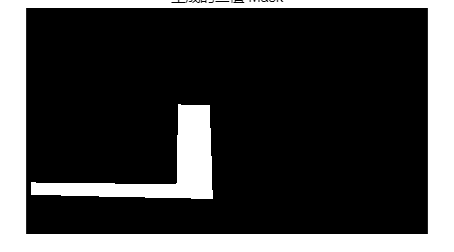

% 读取一张底图
files = dir(fullfile(outputFolder, '*.jpg'));
firstImagePath = fullfile(files(1).folder, files(1).name);
img = imread(firstImagePath);
figure; imshow(img); title('请在图片上绘制不规则 Mask，双击完成');

% 交互式多点绘制多边形 Mask
h = impoly(gca);
position = wait(h);       % 等待用户双击完成
mask = createMask(h);     % 生成与图像同尺寸的二值 Mask

close(gcf);               % 双击完成后自动关闭图像窗口

% 可视化 Mask
figure; imshow(mask); title('生成的二值 Mask');


% 保存为 .mat 文件
save(fullfile(newPath, 'mask.mat'), 'mask');
% 读入并显示图像
firstImagePath = fullfile(outputFolder, sprintf('frame_%05d.jpg', startFrame));
I = imread(firstImagePath);
figure; imshow(I);
title('请拖动矩形框选择 ROI，双击或回车完成');

% 交互式框选 ROI
h = imrect(gca, []);     
pos = wait(h);           % 等待用户完成框选
close(gcf);              % 框选完成后关闭窗口

% 显示结果
ROI = round([pos(1), pos(2), pos(3), pos(4)]);
disp(['ROI = [' num2str(ROI(1)) ', ' num2str(ROI(2)) ', ' ...
      num2str(ROI(3)) ', ' num2str(ROI(4)) ']']);

ROI = [22, 625, 1895, 288]



% 根据高度判断 index
if ROI(4) < 160
    index = 0.4;
elseif ROI(4) >= 160
    index = 1;
end

s = cell(15,2); % To make it more readable, let's create a "settings table"
%Parameter                          %Setting			%Options
s{1,1}= 'Int. area 1';              s{1,2}=128*index;			% window size of first pass
s{2,1}= 'Step size 1';              s{2,2}=64*index;			% step of first pass
s{3,1}= 'Subpix. finder';           s{3,2}=1;			% 1 = 3point Gauss, 2 = 2D Gauss
s{4,1}= 'Mask';                     s{4,2}=mask;			% If needed, supply a binary image mask with the same size as the PIV images
s{5,1}= 'ROI';                      s{5,2}=ROI;			% Region of interest: [x,y,width,height] in pixels, may be left empty to process the whole image
s{6,1}= 'Nr. of passes';            s{6,2}=4;			% 1-4 nr. of passes
s{7,1}= 'Int. area 2';              s{7,2}=32;			% second pass window size
s{8,1}= 'Int. area 3';              s{8,2}=10;			% third pass window size
s{9,1}= 'Int. area 4';              s{9,2}=4;			% fourth pass window size
s{10,1}='Window deformation';       s{10,2}='*line';	% '*spline' is more accurate, but slower
s{11,1}='Repeated Correlation';     s{11,2}=1;			% 0 or 1 : Repeat the correlation four times and multiply the correlation matrices.
s{12,1}='Disable Autocorrelation';  s{12,2}=0;			% 0 or 1 : Disable Autocorrelation in the first pass.
s{13,1}='Correlation style';        s{13,2}=0;			% 0 or 1 : Use circular correlation (0) or linear correlation (1).
s{14,1}='Repeat last pass';			s{14,2}=0;			% 0 or 1 : Repeat the last pass of a multipass analyis
s{15,1}='Last pass quality slope';  s{15,2}=0.025;		% Repetitions of last pass will stop when the average difference to the previous pass is less than this number.

p = cell(10,1);
%Parameter                       %Setting           %Options
p{1,1}= 'ROI';                   p{1,2}=s{5,2};     % same as in PIV settings
p{2,1}= 'CLAHE';                 p{2,2}=1;          % 1 = enable CLAHE (contrast enhancement), 0 = disable
p{3,1}= 'CLAHE size';            p{3,2}=50;         % CLAHE window size
p{4,1}= 'Highpass';              p{4,2}=0;          % 1 = enable highpass, 0 = disable
p{5,1}= 'Highpass size';         p{5,2}=15;         % highpass size
p{6,1}= 'Clipping';              p{6,2}=0;          % 1 = enable clipping, 0 = disable
p{7,1}= 'Wiener';                p{7,2}=0;          % 1 = enable Wiener2 adaptive denoise filter, 0 = disable
p{8,1}= 'Wiener size';           p{8,2}=3;          % Wiener2 window size
p{9,1}= 'Minimum intensity';     p{9,2}=0.0;        % Minimum intensity of input image (0 = no change)
p{10,1}='Maximum intensity';     p{10,2}=1.0;       % Maximum intensity on input image (1 = no change)

pairwise = 0;  % 若需细致跟踪选 0；若只需粗略两两对比选 1
if pairwise == 1
    % 成对独立模式：图像两两配对，不重叠
    if mod(amount,2) == 1   % 判断图像数量是否为奇数
        disp('Image folder should contain an even number of images.')
        % 若为奇数，则剔除最后一张
        amount = amount - 1;
        filenames(size(filenames,1)) = [];
    end
    % 显示配对后的图像数量及配对数
    disp(['Found ' num2str(amount) ' images (' num2str(amount/2) ' image pairs).'])
    % 预分配结果 cell 数组，长度 = 图像对数
    x = cell(amount/2,1);
    y = x;
    u = x;
    v = x;
else
    % 滑动重叠模式：每帧与下一帧配对，共 amount-1 对
    disp(['Found ' num2str(amount) ' images'])
    % 预分配结果 cell 数组，长度 = amount-1
    x = cell(amount-1,1);
    y = x;
    u = x;
    v = x;
end

Found 14 images


typevector = x

typevector = 13×1 cell 数组
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


correlation_map = x

correlation_map = 13×1 cell 数组
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


slicedfilename1=cell(0);
slicedfilename2=cell(0);
j = 1;
for i=1:1+pairwise:amount-1
	slicedfilename1{j}=filenames{i}; % begin
	slicedfilename2{j}=filenames{i+1}; % end
	j = j+1;
end
img1 = imread(fullfile(directory, slicedfilename1{1}));
[H, W] = size(img1);
ROI = p{1,2};  % 取预处理设置中的 ROI

disp(['图像尺寸: ', num2str(H), '×', num2str(W)]);

图像尺寸: 1080×5760


disp(['ROI = [x y width height]: [', num2str(ROI), ']']);

ROI = [x y width height]: [22   625  1895   288]



% 验证 ROI 是否超出边界
if ROI(1)<1 || ROI(2)<1 || ROI(1)+ROI(3)-1>W || ROI(2)+ROI(4)-1>H
    error('ROI 超出图像边界，请检查 p{1,2} 的值');
end

if nr_of_cores > 1
    if misc.pivparpool('size')<nr_of_cores
        misc.pivparpool('open',nr_of_cores);
    end
    parfor i=1:size(slicedfilename1,2)  % index must increment by 1
        [x{i}, y{i}, u{i}, v{i}, typevector{i},correlation_map{i}] = ...
            piv.piv_analysis(directory, slicedfilename1{i}, slicedfilename2{i},p,s,nr_of_cores,false);
    end
else % sequential loop
    for i=1:size(slicedfilename1,2)  % index must increment by 1
        [x{i}, y{i}, u{i}, v{i}, typevector{i},correlation_map{i}] = ...
            piv.piv_analysis(directory, slicedfilename1{i}, slicedfilename2{i},p,s,nr_of_cores,true);
        disp([int2str((i+1)/amount*100) ' %']);
    end
end

正在使用 'Processes' 配置文件启动并行池(parpool)...
27-May-2025 22:38:31: 作业正在运行。正在等待并行池工作进程连接...
已连接到具有 4 个工作进程的并行池。


r = cell(6,1);
%Parameter     %Setting                                     %Options
r{1,1}= 'Calibration factor, 1 for uncalibrated data';      r{1,2}=0.0451;                   % Calibration factor for u
r{2,1}= 'Calibration factor, 1 for uncalibrated data';      r{2,2}=0.0451;                   % Calibration factor for v
r{3,1}= 'Valid velocities [u_min; u_max; v_min; v_max]';    r{3,2}=[-50; 50; -50; 50];  % Maximum allowed velocities, for uncalibrated data: maximum displacement in pixels
r{4,1}= 'Stdev check?';                                     r{4,2}=1;                   % 1 = enable global standard deviation test
r{5,1}= 'Stdev threshold';                                  r{5,2}=7;                   % Threshold for the stdev test
r{6,1}= 'Local median check?';                              r{6,2}=1;                   % 1 = enable local median test
r{7,1}= 'Local median threshold';                           r{7,2}=3;                   % Threshold for the local median test
u_filt=cell(size(u));
v_filt=cell(size(v));
typevector_filt=typevector;
if nr_of_cores >1 % parallel loop
	if misc.pivparpool('size')<nr_of_cores
		misc.pivparpool('open',nr_of_cores);
	end
	parfor PIVresult=1:size(x,1)
		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},r,true);
	end
else % sequential loop
	for PIVresult=1:size(x,1)
		[u_filt{PIVresult,1}, v_filt{PIVresult,1},typevector_filt{PIVresult,1}]= ...
			post_proc_wrapper(u{PIVresult,1},v{PIVresult,1},typevector{PIVresult,1},r,true);
	end
end

outDir = fullfile(newPath, 'Results'); 
if ~exist(outDir,'dir')
    mkdir(outDir);
end
maxvel=[]


maxvel =

     []



% 先统一计算所有时刻的最大速度
numFrames = length(x);
vmax = 0; M_all = cell(1, numFrames);


% ------- 1️⃣ 计算全局最大速度 -------
for t = 1:numFrames
    filt_u = u_filt{t} * 0.0451;
    filt_v = v_filt{t} * 0.0451;
    M = sqrt(filt_u.^2 + filt_v.^2);
    M(isnan(M)) = 0;
    M_all{t} = M;
    vmax = max(vmax, max(M(:)));
end
vthresh = 0.15 * vmax;

% ------- 自定义6段色带（第一段白色）-------
customCmap = [
    1.00 1.00 1.00;  % 白
    0.65 0.81 0.89;  % 浅蓝
    0.12 0.47 0.71;  % 深蓝
    0.20 0.63 0.17;  % 绿
    1.00 0.65 0.00;  % 橙
    0.84 0.10 0.14   % 红
];

% ------- 2️⃣ 处理每帧 -------
for t = 1:numFrames
    fprintf("处理第 %d 帧...\n", t);
    M = M_all{t};
    M(M < vthresh) = 0;

    % 连通域保留前70%面积区域
    BW = M > 0;
    CC = bwconncomp(BW);
    stats = regionprops(CC, 'Area');
    A = [stats.Area];
    [A_sorted, idx] = sort(A, 'descend');
    cumA = cumsum(A_sorted);
    totalA = sum(A_sorted);
    keepIdx = idx(cumA <= 0.9 * totalA);
    mask = false(size(M));
    for i = 1:numel(keepIdx)
        mask(CC.PixelIdxList{keepIdx(i)}) = true;
    end
    M(~mask) = 0;

    % ------- 3️⃣ 重采样到真实坐标系 -------
    X = x{t} * 0.0451;
    Y = y{t} * 0.0451;
    X = X - min(X(:));
    Y = Y - min(Y(:));
    scale = 3;
    [rows, cols] = size(M);
    [Xq, Yq] = meshgrid( ...
        linspace(min(X(:)), max(X(:)), cols * scale), ...
        linspace(min(Y(:)), max(Y(:)), rows * scale) ...
    );
    M_zoom = interp2(X, Y, M, Xq, Yq, 'bicubic');
    M_zoom(M_zoom < 1e-6) = NaN;

    % ------- 4️⃣ 绘图 -------
    xrange = max(Xq(1,:)) - min(Xq(1,:));
    yrange = max(Yq(:,1)) - min(Yq(:,1));
    width_cm  = 15;
    height_cm = width_cm * yrange / xrange * 1.5;

    hFig = figure('Units','centimeters', 'Position',[2, 2, width_cm, height_cm]);
    imagesc('XData', Xq(1,:), 'YData', Yq(:,1), 'CData', M_zoom);
    axis image;
    set(gca, 'YDir', 'reverse');
    colormap(customCmap);
    caxis([0, vmax]);
    set(gca, 'Color', [1 1 1]);

    xlabel('Distance (mm)', 'FontSize', 9, 'FontName', 'Times New Roman');
    ylabel('Depth (mm)', 'FontSize', 9, 'FontName', 'Times New Roman');
    set(gca, 'FontSize', 9, 'FontName', 'Times New Roman');
    grid on;

    % ———— 自动缩小坐标区，为右侧 colorbar 留出空间 ————
    ax    = gca;
    outer = ax.OuterPosition;
    inset = ax.TightInset;
    % 留出约 0.12 归一化宽度给 colorbar
    newWidth = outer(3) - inset(1) - inset(3) - 0.05;
    ax.Position = [outer(1)+inset(1), ...
                   outer(2)+inset(2), ...
                   newWidth, ...
                   outer(4)-inset(2)-inset(4)];

    % 右侧竖直 colorbar
    levels = linspace(0, vmax, 7);
    cb = colorbar(ax, 'eastoutside');
    cb.Ticks      = levels;
    cb.TickLabels = arrayfun(@(v) sprintf('%.2f', v), levels, 'UniformOutput', false);
    ylabel(cb, 'Velocity (m/s)', 'FontSize', 9, 'FontName', 'Times New Roman');
    set(cb, 'FontSize', 9, 'FontName', 'Times New Roman');

    % 保存（高分辨率、无白边）
    set(hFig, 'PaperUnits','centimeters');
    set(hFig, 'PaperPosition',[0 0 width_cm height_cm]);
    set(hFig, 'PaperSize',[width_cm height_cm]);
    [~, name, ~] = fileparts(slicedfilename1{t});
    savePath = fullfile(outDir, [name '_vmag_realxy.png']);
    print(hFig, savePath, '-dpng', '-r600');
    close(hFig);
end

处理第 1 帧...
处理第 2 帧...
处理第 3 帧...
处理第 4 帧...
处理第 5 帧...
处理第 6 帧...
处理第 7 帧...
处理第 8 帧...
处理第 9 帧...
处理第 10 帧...
处理第 11 帧...
处理第 12 帧...
处理第 13 帧...





% for t = 1: length(x)
%     t
%     % 获取图像大小（根据坐标尺寸计算）
%     X = x{t};
%     Y = y{t};
%     xrange = max(X(:)) - min(X(:));
%     yrange = max(Y(:)) - min(Y(:));
%     width_cm = 30;  % 自定义输出宽度（单位：cm）
%     height_cm = width_cm * yrange / xrange;
%     u_filt{t}=u_filt{t}*0.0451;
%     v_filt{t}=v_filt{t}*0.0451;
%     % 计算矢量幅值
%     filt_u = u_filt{t};
%     filt_v = v_filt{t};
%     M = sqrt(filt_u.^2 + filt_v.^2);  % M 为速度幅值矩阵
%     maxvel(t)=max(max(M))
%     X = x{t};
%     Y = y{t};
%     % 设置色彩范围
%     mmin = min(M(~isnan(M)));
%     mmax = max(M(~isnan(M)));
%     hFig = figure('Units','centimeters', 'Position',[2, 2, width_cm, height_cm]);
%     % 绘制速度云图
%     imagesc('XData', X(1,:), 'YData', Y(:,1), 'CData', M);
%     set(gca, 'YDir', 'reverse');  % 图像坐标方向一致
%     axis image;
%     colormap(jet(256));
%     caxis([mmin, mmax]);
%     cb = colorbar;
%     set(cb, 'FontName', 'Times New Roman', 'FontSize', 10);
%     ylabel(cb, 'Velocity (m/s)', 'FontName', 'Times New Roman', 'FontSize', 10);
%     % 设置透明区域（NaN 不显示）
%     hImg = get(gca, 'Children');
%     set(hImg, 'AlphaData', ~isnan(M));
%     set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
%     % 保存图像
%     [~, name, ~] = fileparts(slicedfilename1{t});
%     savePath = fullfile(outDir, [name '_vmag.png']);
%     print(hFig, savePath, '-dpng', '-r600');
%     set(hFig, 'HandleVisibility', 'off');  % 防止销毁回调触发错误
%     close(hFig);
% end

if nr_of_cores >1 % parallel
	poolobj = gcp('nocreate'); % GET the current parallel pool
	if ~isempty(poolobj ); delete(poolobj );end
	clear local_cluster;
end

save(fullfile(newPath, [filenames{1} '_' filenames{end} '_' num2str(amount) '_frames_result_.mat']));